# Problema 1

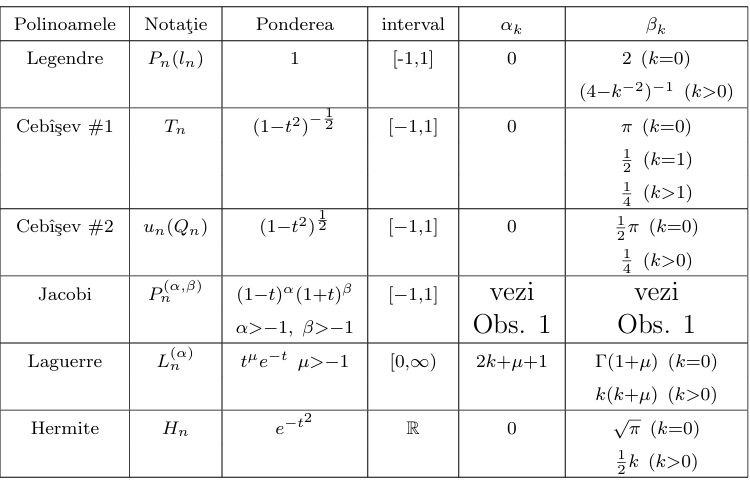

## Gauss Legendre

function [noduri, coeficienti] = gauss_legendre(n)
%   Input:
%       n - numarul de noduri (puncte de evaluare)
%
%   Output:
%       nodes     - pozitiile nodurilor (radacinile polinomului Legendre)
%       weights   - coeficientii de integrare (ponderele asociate)

    % Initializam coeficientii pentru matricea tridiagonala (Jacobi)
    alpha = zeros(n, 1);
    beta = zeros(n-1, 1);

    % Calculam coeficientii beta conform formulei standard pentru Legendre
    for k = 1:n-1
        beta(k) = 1 / sqrt(4 - 1/(k^2));
    end

    % Construim matricea Jacobi tridiagonala simetrica
    J = diag(alpha) + diag(beta, 1) + diag(beta, -1);

    % Calculam valorile proprii (nodes) si vectorii proprii
    [V, D] = eig(J);
    noduri = diag(D);       

    % Sortam nodurile si ajustam vectorii proprii corespunzatori
    [noduri, ord] = sort(noduri);
    V = V(:, ord);

    % Formula coeficientilor (pondere) pentru Gauss-Legendre:
    coeficienti = 2 * V(1,:).^2;  
end

## Cebisev 1

function [noduri, coeficienti] = gauss_chebyshev1(n)
%   Input:
%       n - numarul de noduri
%
%   Output:
%       nodes    - valorile nodurilor (cosinusuri echidistante)
%       weights  - coeficientii de integrare, egali (pi/n)

    k = 1:n; % indexul nodurilor

    % Nodurile sunt cosinusuri echidistante in [0, pi]
    noduri = cos((2*k - 1) * pi / (2 * n));

    % Toti coeficientii sunt egali cu pi/n
    coeficienti = (pi / n) * ones(1, n);
end

## Cebisev 2

function [noduri, coeficienti] = gauss_chebyshev2(n)
%   Input:
%       n - numarul de noduri
%
%   Output:
%       nodes    - valorile nodurilor
%       weights  - coeficientii de integrare

    k = 1:n;% indexul nodurilor

    % Nodurile sunt date de cos(pi * k / (n + 1))
    noduri = cos(pi * k / (n + 1));

    % Coeficientii depend de sin^2(k * pi / (n + 1))
    coeficienti = pi / (n + 1) * sin(pi * k / (n + 1)).^2;
end

## Jacobi

function [noduri, coeficienti] = gauss_jacobi(n, alpha, beta)
%   Input:
%       n     - numarul de noduri
%       alpha - parametru al ponderei (> -1)
%       beta  - parametru al ponderei (> -1)
%
%   Output:
%       nodes    - valorile nodurilor (radacini polinom Jacobi)
%       weights  - coeficientii asociati nodurilor

    if alpha <= -1 || beta <= -1
        error('alpha si beta trebuie sa fie > -1');
    end

    a = zeros(n, 1);      % coeficientii diagonali α_k
    b = zeros(n-1, 1);    % coeficientii sub/supradiagonali β_k

    for k = 0:n-1
        if k > 0
            num = 4*k*(k + alpha)*(k + beta)*(k + alpha + beta);
            den = (2*k + alpha + beta)^2 * (2*k + alpha + beta + 1) * (2*k + alpha + beta - 1);
            b(k) = sqrt(num / den);
        end
        a(k+1) = (beta^2 - alpha^2) / ((2*k + alpha + beta) * (2*k + alpha + beta + 2));
    end

    % Matricea Jacobi
    J = diag(a) + diag(b, 1) + diag(b, -1);

    % Calculam valorile si vectorii proprii
    [V, D] = eig(J);
    noduri = diag(D);
    [noduri, ord] = sort(noduri);
    V = V(:, ord);

    % Coeficientii: formula generalizata (beta0 este constanta de normalizare)
    beta0 = 2^(alpha + beta + 1) * gamma(alpha + 1) * gamma(beta + 1) / gamma(alpha + beta + 2);
    coeficienti = beta0 * V(1,:).^2;
end

## Laguerre

function [noduri, coeficienti] = gauss_laguerre(n)
%   Input:
%       n - numarul de noduri
%
%   Output:
%       nodes    - valorile nodurilor (radacinile polinomului Laguerre)
%       weights  - coeficientii de integrare

    alpha = zeros(n, 1);
    beta = sqrt((1:n-1)');  % coeficientii βk
    beta0 = 1;

    J = diag(alpha) + diag(beta, 1) + diag(beta, -1);

    % Valorile proprii = noduri, vectorii proprii pentru coeficienti
    [V, D] = eig(J);
    noduri = diag(D);
    [noduri, ord] = sort(noduri);
    V = V(:, ord);

    % Coeficientii A_k = beta0 * (v_1k)^2
    coeficienti = beta0 * V(1,:).^2;
end

## Hermite

function [noduri, coeficienti] = gauss_hermite(n)
%   Input:
%       n - numarul de noduri
%
%   Output:
%       nodes    - radacinile polinomului Hermite H_n(x)
%       weights  - coeficientii asociati (pentru integrare)

    alpha = zeros(n, 1);
    beta = sqrt((1:n-1) / 2)';
    beta0 = sqrt(pi);

    J = diag(alpha) + diag(beta, 1) + diag(beta, -1);

    [V, D] = eig(J);
    noduri = diag(D);
    [noduri, ord] = sort(noduri);
    V = V(:, ord);
    
    coeficienti = beta0 * V(1,:).^2;
end

n = 5;

fprintf("=== Gauss-Legendre ===\n");

=== Gauss-Legendre ===


[x, A] = gauss_legendre(n);
disp("Noduri:"); disp(x');

Noduri:
   -0.9062   -0.5385    0.0000    0.5385    0.9062



disp("Coeficienti:"); disp(A');

Coeficienti:
    0.2369
    0.4786
    0.5689
    0.4786
    0.2369




fprintf("\n=== Gauss-Chebyshev Tip I ===\n");


=== Gauss-Chebyshev Tip I ===


[x, A] = gauss_chebyshev1(n);
disp("Noduri:"); disp(x);

Noduri:
    0.9511    0.5878    0.0000   -0.5878   -0.9511



disp("Coeficienti:"); disp(A);

Coeficienti:
    0.6283    0.6283    0.6283    0.6283    0.6283




fprintf("\n=== Gauss-Chebyshev Tip II ===\n");


=== Gauss-Chebyshev Tip II ===


[x, A] = gauss_chebyshev2(n);
disp("Noduri:"); disp(x);

Noduri:
    0.8660    0.5000    0.0000   -0.5000   -0.8660



disp("Coeficienti:"); disp(A);

Coeficienti:
    0.1309    0.3927    0.5236    0.3927    0.1309




fprintf("\n=== Gauss-Laguerre ===\n");


=== Gauss-Laguerre ===


[x, A] = gauss_laguerre(n);
disp("Noduri:"); disp(x');

Noduri:
   -2.8570   -1.3556   -0.0000    1.3556    2.8570



disp("Coeficienti:"); disp(A');

Coeficienti:
    0.0113
    0.2221
    0.5333
    0.2221
    0.0113




fprintf("\n=== Gauss-Hermite ===\n");


=== Gauss-Hermite ===


[x, A] = gauss_hermite(n);
disp("Noduri:"); disp(x');

Noduri:
   -2.0202   -0.9586    0.0000    0.9586    2.0202



disp("Coeficienti:"); disp(A');

Coeficienti:
    0.0200
    0.3936
    0.9453
    0.3936
    0.0200




fprintf("\n=== Gauss-Jacobi (alpha = 0.5, beta = 0.5) ===\n");


=== Gauss-Jacobi (alpha = 0.5, beta = 0.5) ===


[x, A] = gauss_jacobi(n, 0.5, 0.5);
disp("Noduri:"); disp(x');

Noduri:
   -0.8660   -0.5000   -0.0000    0.5000    0.8660



disp("Coeficienti:"); disp(A');

Coeficienti:
    0.1309
    0.3927
    0.5236
    0.3927
    0.1309

